clear;

Read the numeric 

x = readcell('AvgFeatures.xlsx')

x = 15×47 cell array
    {'Company'              }    {'AAPL'    }    {'NOW'      }    {'MSFT'    }    {'GOOGL'  }    {'NFLX'    }    {'YELP'       }    {'HD'      }    {'W'       }    {'AMZN'    }    {'COST'    }    {'HSY'    }    {'KDP'     }    {'ELF'        }    {'CLX'     }    {'XOM'     }    {'CVX'     }    {'SHEL'      }    {'MPC'        }    {'HAL'    }    {'JPM'    }    {'MS'     }    {'V'       }    {'UNH'     }    {'PFE'     }    {'DXCM'     }    {'RTX'     }    {'FDX'     }    {'LHX'    }    {'TTEK'    }    {'UHAL'    }    {'ECL'     }    {'SHW'     }    {'SCCO'   }    {'CLF'      }    {'LIN'     }    {'PLD'     }    {'AMT'     }    {'EXR'     }    {'KIM'     }    {'SLG'     }    {'D'      }    {'NEE'        }    {'DUK'     }    {'AEP'       }    {'ES'      }    {'PCG'    }
    {'Shares Outstanding'   }    {[ 16.8191]}    {[   0.1956]}    {[  7.5335]}    {[13.2342]}    {[  0.4388]}    {[     0.0762]}    {[  1.0544]}    {[  0.1038]}    {[ 10.1174]}    {[  0.4420]}    {[ 0.14

**The Problem: Cluster the Companies**

I attempt to build a neural network that clusters companies into natural classes, such that similar classes are grouped together. Each companies is described by the average features: Shares Outstanding, ROA, ROE, Profit Margin, Current Ratio, Debt to Equity Ratio, Debt to Asset Ratio, Cash Ratio, Debt to Capital Ratio, EPS Growth, P/S Ratio, P/E Ratio, P/B Ratio, Financial Leverage

I would like to group samples into classes based on the similarity between companies. 

Self-organizing maps (SOMs) is used for classifications. SOM can cluster data with any dimensions and shapes and connected feature spaces. 

companyNames = x(1, 2:end)

companyNames = 1×46 cell array
    {'AAPL'}    {'NOW'}    {'MSFT'}    {'GOOGL'}    {'NFLX'}    {'YELP'}    {'HD'}    {'W'}    {'AMZN'}    {'COST'}    {'HSY'}    {'KDP'}    {'ELF'}    {'CLX'}    {'XOM'}    {'CVX'}    {'SHEL'}    {'MPC'}    {'HAL'}    {'JPM'}    {'MS'}    {'V'}    {'UNH'}    {'PFE'}    {'DXCM'}    {'RTX'}    {'FDX'}    {'LHX'}    {'TTEK'}    {'UHAL'}    {'ECL'}    {'SHW'}    {'SCCO'}    {'CLF'}    {'LIN'}    {'PLD'}    {'AMT'}    {'EXR'}    {'KIM'}    {'SLG'}    {'D'}    {'NEE'}    {'DUK'}    {'AEP'}    {'ES'}    {'PCG'}


featureNames = x(2:end,1)

featureNames = 14×1 cell array
    {'Shares Outstanding'   }
    {'ROA'                  }
    {'ROE'                  }
    {'Profit Margin'        }
    {'Current Ratio'        }
    {'Debt to Equity Ratio' }
    {'Debt to Asset Ratio'  }
    {'Cash Ratio'           }
    {'Debt to Capital Ratio'}
    {'EPS Growth'           }
    {'P/S Ratio'            }
    {'P/E Ratio'            }
    {'P/B Ratio'            }
    {'Financial Leverage'   }


Extract data

x = x(2:end, 2:end)

x = 14×46 cell array
    {[ 16.8191]}    {[   0.1956]}    {[  7.5335]}    {[13.2342]}    {[  0.4388]}    {[     0.0762]}    {[  1.0544]}    {[  0.1038]}    {[ 10.1174]}    {[  0.4420]}    {[ 0.1476]}    {[  1.3127]}    {[     0.0520]}    {[  0.1249]}    {[  4.1922]}    {[  1.8921]}    {[    7.4708]}    {[     0.5243]}    {[ 0.8870]}    {[ 3.0289]}    {[ 1.6872]}    {[  1.9264]}    {[  0.9408]}    {[  5.6290]}    {[   0.3797]}    {[  1.2523]}    {[  0.2581]}    {[ 0.1814]}    {[  0.2704]}    {[  0.0196]}    {[  0.2862]}    {[  0.2656]}    {[ 0.7746]}    {[   0.4272]}    {[  0.5108]}    {[  0.7610]}    {[  0.4538]}    {[  0.1482]}    {[  0.5311]}    {[  0.0716]}    {[ 0.8025]}    {[     1.9750]}    {[  0.7529]}    {[    0.5072]}    {[  0.3404]}    {[ 1.5014]}
    {[  5.9209]}    {[   1.2748]}    {[  4.4061]}    {[ 4.3712]}    {[  2.4581]}    {[     1.3251]}    {[  5.3346]}    {[ -5.2867]}    {[  1.6134]}    {[  2.2297]}    {[ 3.8799]}    {[  0.7765]}    {[     1.5512]}    {[  2.5091]}   

x = cell2mat(x)

x = 1.0e+03 *

    0.0168    0.0002    0.0075    0.0132    0.0004    0.0001    0.0011    0.0001    0.0101    0.0004    0.0001    0.0013    0.0001    0.0001    0.0042    0.0019    0.0075    0.0005    0.0009    0.0030    0.0017    0.0019    0.0009    0.0056    0.0004    0.0013    0.0003    0.0002    0.0003    0.0000    0.0003    0.0003    0.0008    0.0004    0.0005    0.0008    0.0005    0.0001    0.0005    0.0001    0.0008    0.0020    0.0008    0.0005    0.0003    0.0015
    0.0059    0.0013    0.0044    0.0044    0.0025    0.0013    0.0053   -0.0053    0.0016    0.0022    0.0039    0.0008    0.0016    0.0025    0.0015    0.0014    0.0010    0.0013    0.0008    0.0003    0.0003    0.0044    0.0019    0.0020    0.0015    0.0006    0.0049    0.0134    0.0335    0.0010    0.0012    0.0022    0.0046    0.0025    0.0012    0.0010    0.0009    0.0014    0.0010    0.0002    0.0005    0.0009    0.0005    0.0007    0.0005   -0.0005
    0.0290    0.0031    0.0101    0.0060    0.0074    0.0178   

Create and train Self-Organizing Map (SOM)

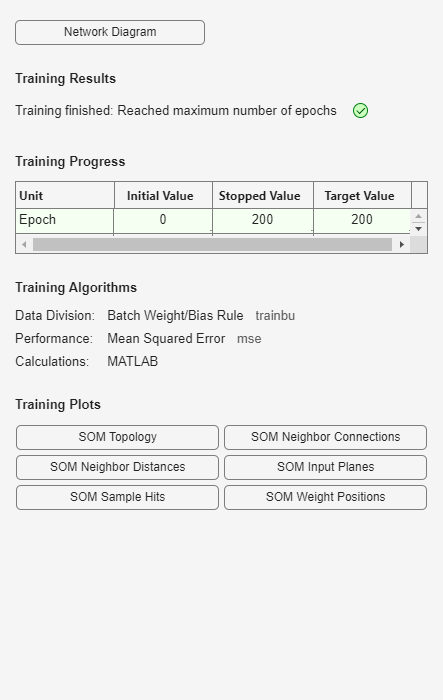

net = selforgmap([3 3]); 
[net,tr] = train(net,x);

Visualize SOM

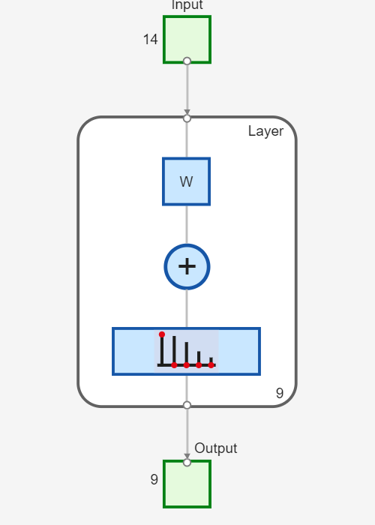

view(net);

The SOM is used to compute the class vectors of each of the training inputs. These classifications cover the feature by the company, and can now be used to classify new company accordingly. The network output will be a 14x46 matrix, where each ith column represents the jth cluster for each ith input vector with a 1 in its jth element.

y = net(x);

The function `vec2ind` returns the index of the neuron with an output of 1, for each vector. The indices will range between 1 and 9 for the 9 clusters represented by the 9 neurons.

classes = vec2ind(y);

classes =      7     7     7     7     2     9     7     7     2     7     7     7     6     7     7     7     1     5     7     7     7     7     7     7     7     7     7     7     2     4     7     7     7     8     7     7     7     7     7     7     7     9     7     7     7     7


`plotsomtop` plots the SOM topology of 9 neurons positioned in an 3x3 hexagonal grid. Each neuron has learned to represent a different class of company, with adjacent neurons typically representing similar classes. The index of the neurons points out the locations of SOM grid. For example the index 1 represents position (1,1), I2 represents (2,1), I3 represents (3,1), I4 represents (1,2) I5 represents (2,2), I6 represents (3,2) , I7 represents (1,3), I8 represents (2,3), I9 represents (3,3).

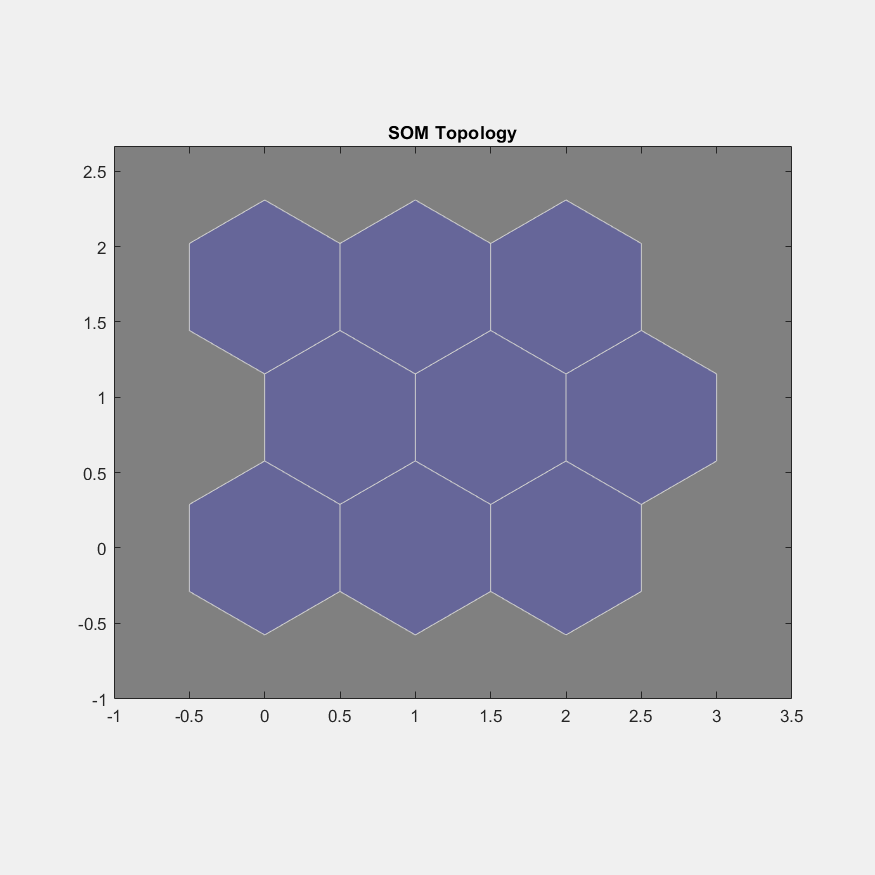

plotsomtop(net);

% Optional: Display mappings
for i = 1:numel(companyNames)
    fprintf('Company: %-20s → Neuron Index: %d\n', companyNames{i}, classes(i));
end

Company: AAPL                 → Neuron Index: 7
Company: NOW                  → Neuron Index: 7
Company: MSFT                 → Neuron Index: 7
Company: GOOGL                → Neuron Index: 7
Company: NFLX                 → Neuron Index: 2
Company: YELP                 → Neuron Index: 9
Company: HD                   → Neuron Index: 7
Company: W                    → Neuron Index: 7
Company: AMZN                 → Neuron Index: 2
Company: COST                 → Neuron Index: 7
Company: HSY                  → Neuron Index: 7
Company: KDP                  → Neuron Index: 7
Company: ELF                  → Neuron Index: 6
Company: CLX                  → Neuron Index: 7
Company: XOM                  → Neuron Index: 7
Company: CVX                  → Neuron Index: 7
Company: SHEL                 → Neuron Index: 1
Company: MPC                  → Neuron Index: 5
Company: HAL                  → Neuron Index: 7
Company: JPM                  → Neuron Index: 7
Company: MS                   → Neuron I

These are 38 companies at the same spot (index 7) . First, we find indices where the neuron index is 7.

fprintf('Companies at Neuron Index 7:\n');

Companies at Neuron Index 7:


idx7=find(classes ==7);

idx7 =      1     2     3     4     7     8    10    11    12    14    15    16    19    20    21    22    23    24    25    26    27    28    31    32    33    35    36    37    38    39    40    41    43    44    45    46


for i = 1:prod(size(idx7))
    fprintf('%s,', companyNames{idx7(i)});
end

AAPL,NOW,MSFT,GOOGL,HD,W,COST,HSY,KDP,CLX,XOM,CVX,HAL,JPM,MS,V,UNH,PFE,DXCM,RTX,FDX,LHX,ECL,SHW,SCCO,LIN,PLD,AMT,EXR,KIM,SLG,D,DUK,AEP,ES,PCG,

Now, all the companies is `AAPL,NOW,MSFT,GOOGL,HD,W,COST,HSY,KDP,CLX,XOM,CVX,HAL,JPM,MS,V,UNH,PFE,DXCM,RTX,FDX,LHX,ECL,SHW,SCCO,LIN,PLD,AMT,EXR,KIM,SLG,D,DUK,AEP,ES,PCG`

Right now, we not using the plotsomtop topology because we want to use the features first. 

We apply the `plotsomhits` to show Areas of neurons with large numbers of hits indicate numbers of company representing similar highly populated regions of the feature space. Whereas areas with few hits indicate sparsely populated regions of the feature space.

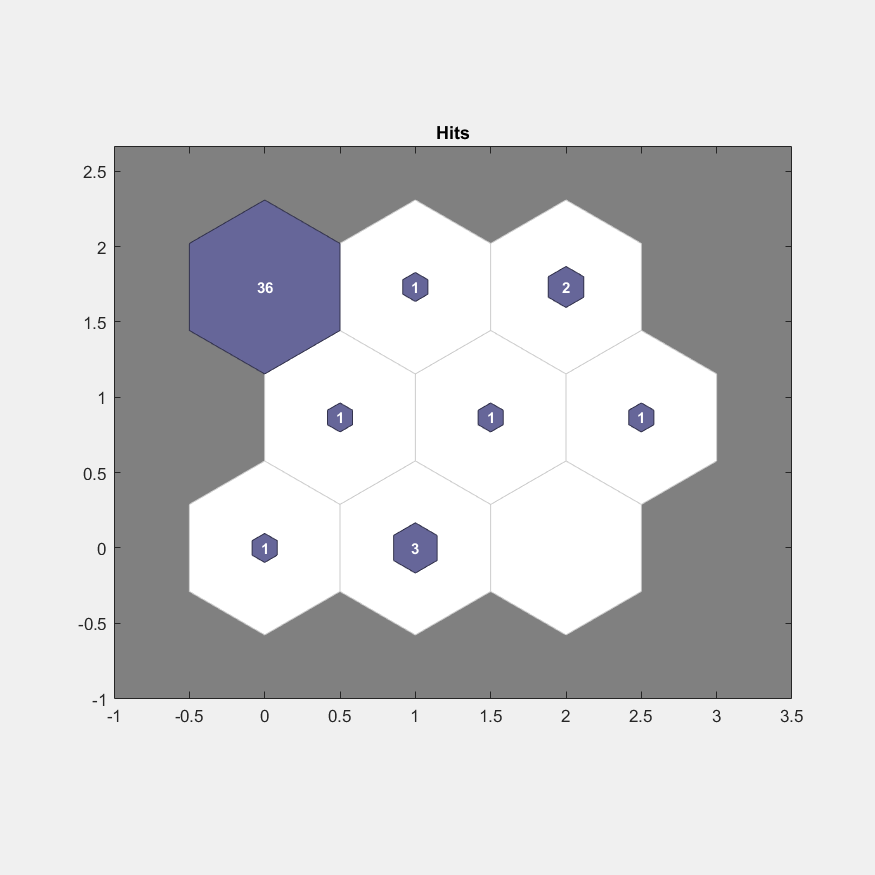

plotsomhits(net, x);

`plotsomnc` shows the neuron neighbor connections. Neighbors typically classify similar feaature.

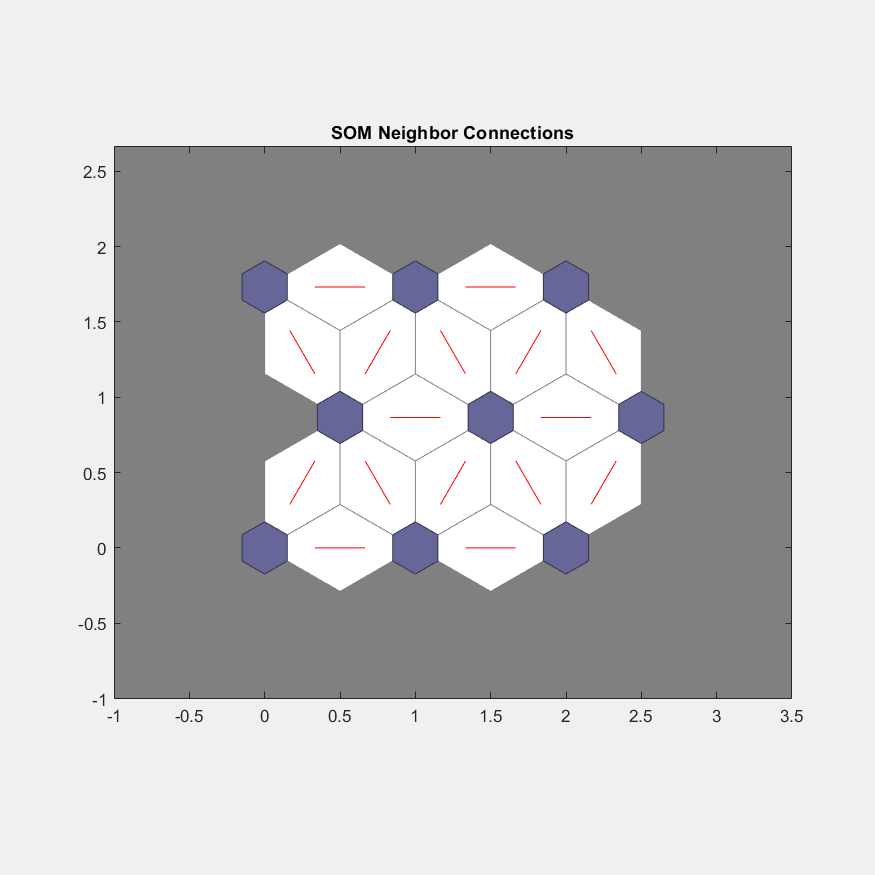

plotsomnc(net);

`plotsomnd` shows how distant (in terms of Euclidian distance) each neuron's class is from its neighbors. Connections which are bright indicate highly connected areas of the input space. While dark connections indicate classes representing regions of the feature which are far apart.

Long borders of dark connections separating large regions of the input space indicate that the classes on either side of the border represent company with  different features.

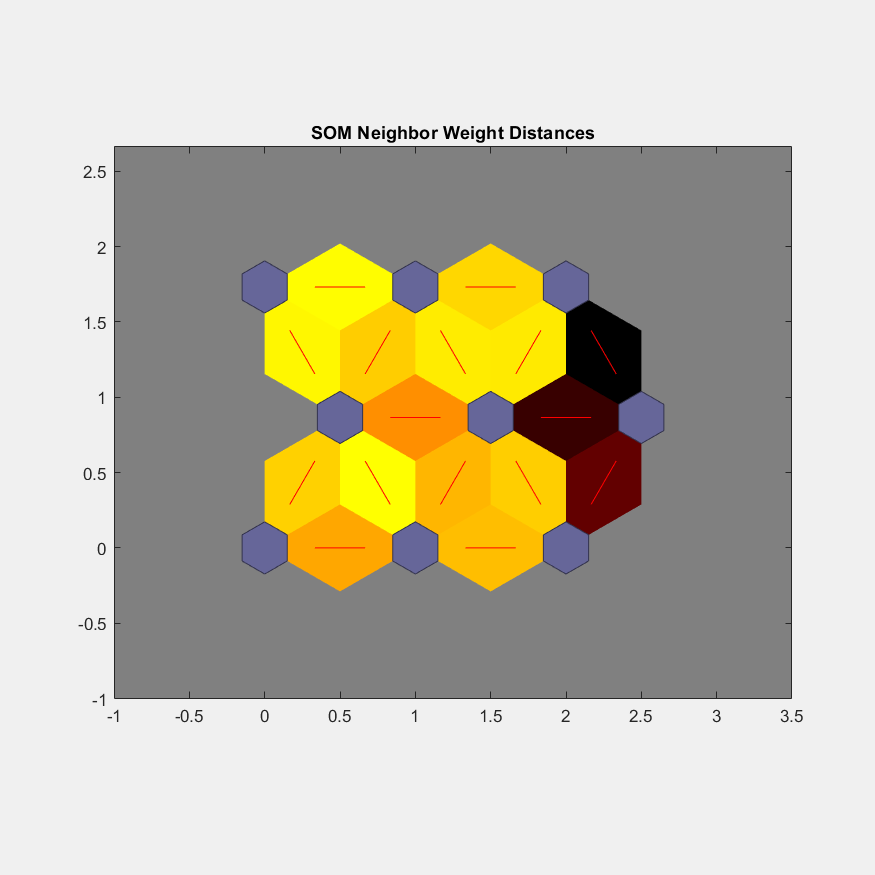

plotsomnd(net);

This example illustrated how to design a neural network that clusters company based on four of their characteristics.

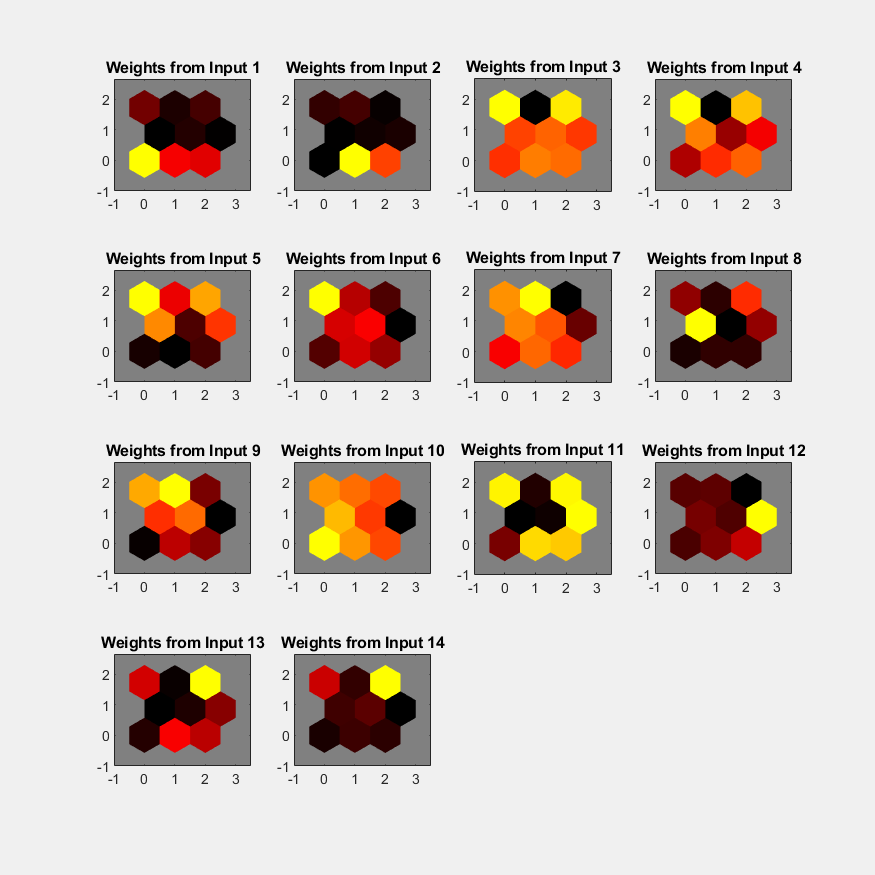

plotsomplanes(net);